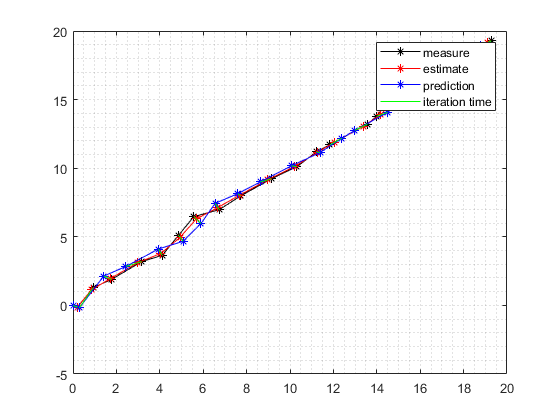

clear variables; close all;clc
% unscented kalman filter example 2
% tracking of an airplane
% states = (distance, velocity, altitude) = (x, xdot, y)
% measures = (range, bearing) = (slant, elevation angle) = (r, etha)
% 

% number of measures
n = 20;
% std of the two measures (sensors)
std_x = 0.3;
std_y = 0.3;
% generate measures
zs = [(0:n-1)+randn(1,n)*std_x; (0:n-1)+randn(1,n)*std_y];
% dimensions
dim_x = 4;
dim_z = 2;
% time step
dt = 1;
% mean
x = [0, 0, 0, 0]';
% covariance
P = eye(4);
% process noise covariance
Q(1:2,1:2) = [0.25*dt^4 0.5*dt^3;0.5*dt^3 dt^2]*0.02;
Q(3:4,3:4) = [0.25*dt^4 0.5*dt^3;0.5*dt^3 dt^2]*0.02;
% measure noise covariance
R = diag([std_x^2 std_y^2]);
F = [1, dt, 0;0, 1, 0;0, 0, 1];
H = [1, 0, 0, 0; 0, 0, 1, 0];

    radar_x = 0;
    radar_y = 0;
    dx = x(0) - radar_x;
    dy = x(2) - radar_y;
    slant_range = sqrt(dx^2 + dy^2)
    elevation_angle = atan2(dy, dx)
    return [slant_range, elevation_angle]
    
% (non linear) state transition function
f = @(x) F*x;
% (non linear) measurement function
h = @(x) H*x;
% sigma points deterministic sampling
alpha = 0.1;
beta = 2;
kappa = -1;
x_posterior = zeros(dim_x,n);
x_prior = zeros(dim_x,n);
for ii=1:n
    z =  zs(:,ii);     
    % predict
    [sigmas,Wm,Wc] = merweScaledSigmaPoints(alpha, beta, kappa, dim_x, x, P);
    sigmas_f = f(sigmas);
    % unscented transformation
    [xp, Pp] = unscented_transform(sigmas_f, Wm, Wc, Q);
    x_prior(:,ii) = xp;

    % update (correct)
    sigmas_h = h(sigmas_f);
    % unscented transformation
    [zp, Pz] = unscented_transform(sigmas_h, Wm, Wc, R);
    % cross variance
    Pxz = (sigmas_f-xp)*diag(Wc)*(sigmas_h-zp)';
    % kalman gain
    K = Pxz/(Pz);
    % residual
    y=z-zp;
    % posterior mean
    x=xp+K*y;
    % posterior covariance
    P=Pp-K*Pz*K';
    x_posterior(:,ii) = x;
end

plot(zs(1,:),zs(2,:),'-*k')
grid minor; hold on;
plot(x_posterior(1,:),x_posterior(3,:),'-*r')
plot(x_prior(1,:),x_prior(3,:),'-*b')
for ii=1:n
    line([zs(1,ii) x_prior(1,ii)],[zs(2,ii) x_prior(3,ii)],'Color','g');
end
legend('measure','estimate','prediction','iteration time')